A = imread('table.png');
B = imread('letter.png');
M = imread('word_mask.png');
mask = M(:,:,1) > 128;

%mixing gradients
num_of_cloned_pixels = sum(sum(mask)) %#ok<NASGU> 

num_of_cloned_pixels = 86575

t = cputime;
C = importing_gradients(A, B, mask);
duration = cputime - t %#ok<NASGU> 

duration = 14.0156

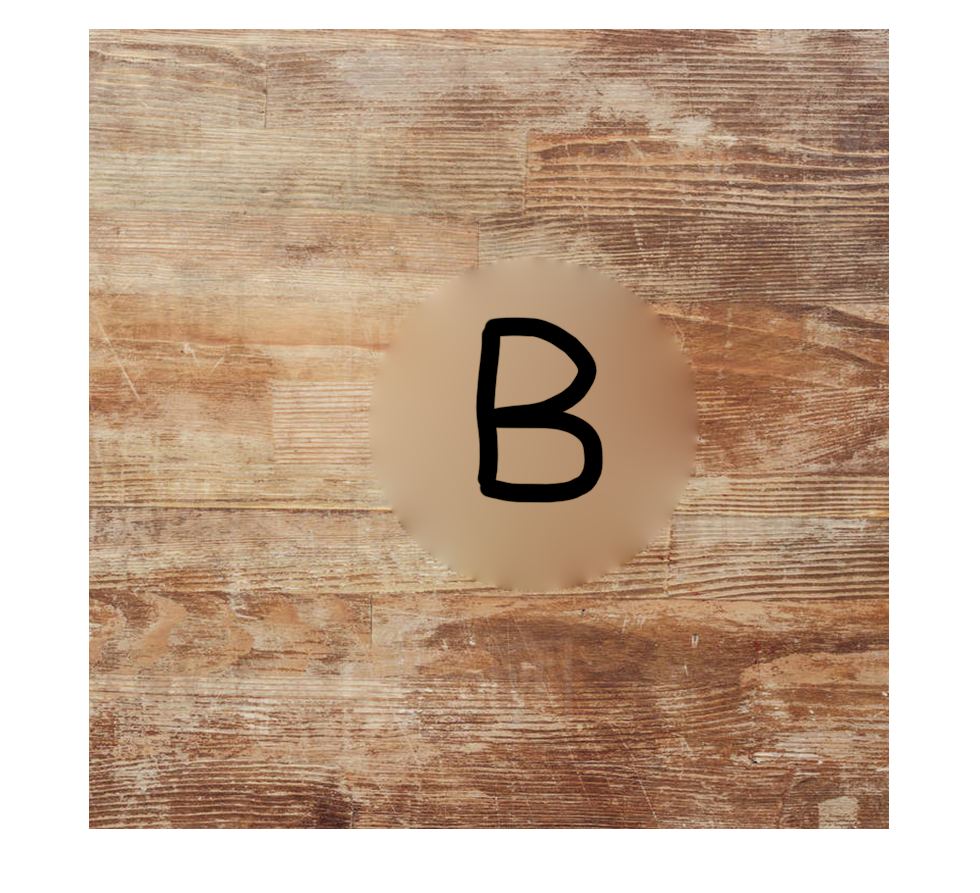

imshow(C)

%mixing gradients
num_of_cloned_pixels = sum(sum(mask))

num_of_cloned_pixels = 86575

t = cputime;
C = mixing_gradients(A, B, mask);
duration = cputime - t

duration = 19.3125

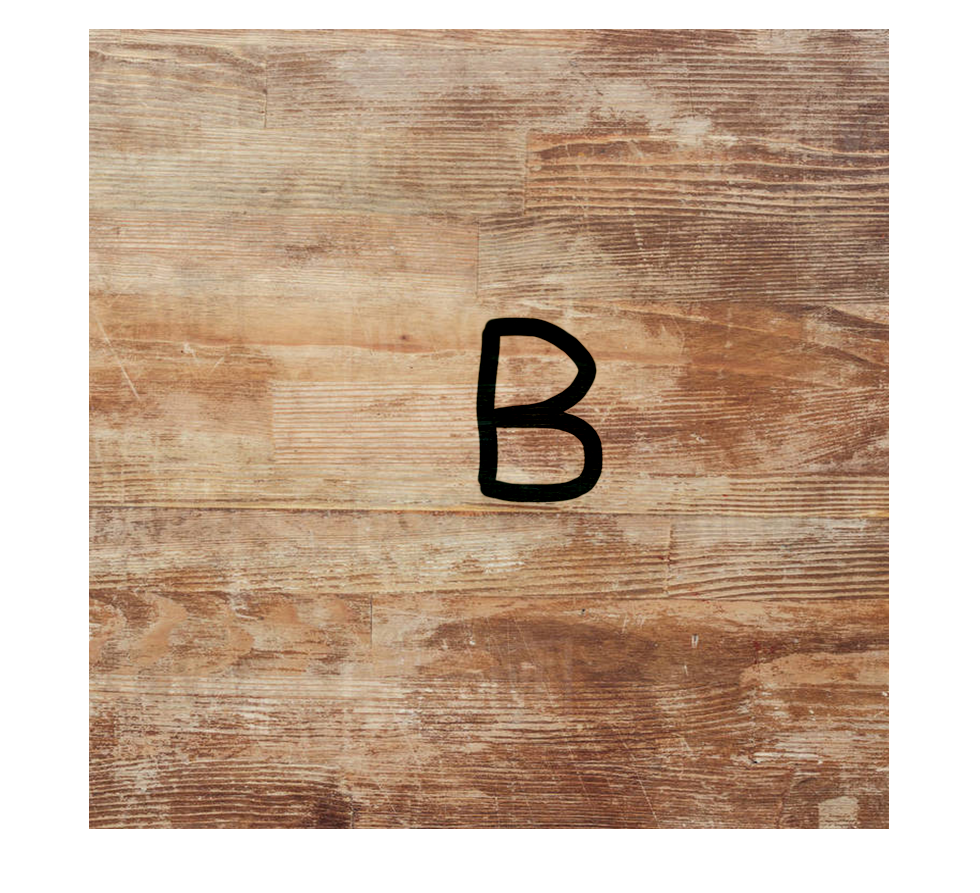

imshow(C)

% vectorized implementation of make map

function [map, inv_map] = make_map(mask)
    [x, y] = size(mask);
    
    % calculate all the number of pixels in the interior
    inner_entries = int32(sum(sum(uint8(mask))));
    
    % map from index of variables to location in the image
    [r, c] = find(mask);
    map = [r c];
    
    % map from location in the image to index of variables
    inv_map = zeros([x, y], 'uint32');
    % assign values to inv_map
    indices = 1:inner_entries;
    r = map(indices, 1);
    c = map(indices, 2);
    idx = sub2ind(size(inv_map), r,c);
    inv_map(idx) = indices;
end

% check inner
function flag = is_inner(x_, y_, x, y)
    flag = 1 <= x_ & x_ <= x & 1 <= y_ & y_ <= y;
end

% generate the seamless cloned image from background image, source image
% and mask
function out_put_image = importing_gradients(background_image, source_image, mask)
   % generate the 2 maps
   [map, inv_map] = make_map(mask);
   
%% generate the Poisson equation            
   [num_entries, ~] = size(map);
   % The coefficients of the equation Mq = b
   M = spalloc(num_entries, num_entries, num_entries * 5);
   b = zeros([num_entries, 3]);
   % The canvas of the output
   image = zeros(size(background_image), 'like', background_image);
   [x, y, ~] = size(background_image);
   tmp = zeros([x, y], 'like', background_image);
   % The kernel to help calculate the gradients
   kernel = [
       0, -1, 0;
       -1, 4, -1;
       0, -1, 0];
   % calculate the gradients in each channel
   
   % importing gradients
   gradients(:, :, 1) = conv2(source_image(:,:,1), kernel, 'same');
   gradients(:, :, 2) = conv2(source_image(:,:,2), kernel, 'same');
   gradients(:, :, 3) = conv2(source_image(:,:,3), kernel, 'same');

   % To make code simpler, embed all the offsets of neighbour into one
   % vector
   directions = [1, 0; -1, 0; 0, 1; 0, -1];
   % calculate the coefficients of the Poisson equation i.e.
   % |N_p| f_p - sum(f_q) = sum(f_q^*) + sum(v_pq)
   for i = 1:num_entries
      pos = map(i, :);
      neighbours = 0;
      for k = 1:4
          temp = pos + directions(k, :);
          % the pixel needs to be in the image
          if is_inner(temp(1), temp(2), x, y)
              % add -sum(f_q) to the coefficient matrix
              if mask(temp(1), temp(2))
                  ind = inv_map(temp(1), temp(2));
                  M(i, ind) = -1;
              else
                  % add boundary conditions
                  b(i,:) = b(i,:) + reshape(double(background_image(temp(1), temp(2),:)), [1,3]);
              end
              neighbours = neighbours + 1;
          end
      end
      % |N_p| f_p
      M(i, i) = neighbours;
      % sum(v_pq)
      b(i,:) = b(i,:) + reshape(gradients(pos(1), pos(2),:), [1,3]);
   end   
   
%% solve the linear system, poisson equation
   sol = M \ b;
   % color the image by the solution of the linear system.  
   L = 1 : num_entries; 
   r = map(L,1);
   c = map(L,2);
   % change the (i, j) indices parts into integer indices
   idx = sub2ind(size(inv_map), r,c);
   % color each channel
   tmp(idx) = sol(:,1);
   image(:, :, 1) = tmp;
   tmp(idx) = sol(:,2);
   image(:, :, 2) = tmp;
   tmp(idx) = sol(:,3);
   image(:, :, 3) = tmp;
   % generate the final image
   out_put_image = uint8(mask) .* image + uint8(1 - mask) .* background_image;
end

% generate the seamless cloned image from background image, source image
% and mask
function out_put_image = mixing_gradients(background_image, source_image, mask)
   % generate the 2 maps
   [map, inv_map] = make_map(mask);
   
%% generate the Poisson equation            
   [num_entries, ~] = size(map);
   % The coefficients of the equation Mq = b
   M = spalloc(num_entries, num_entries, num_entries * 5);
   b = zeros([num_entries, 3]);
   % The canvas of the output
   image = zeros(size(background_image), 'like', background_image);
   [x, y, ~] = size(background_image);
   tmp = zeros([x, y], 'like', background_image);
   % The kernel to help calculate the gradients
   kernel = [
       0, -1, 0;
       -1, 4, -1;
       0, -1, 0];
   
   % To make code simpler, embed all the offsets of neighbour into one
   % vector
   directions = [1, 0; -1, 0; 0, 1; 0, -1];
   % calculate the coefficients of the Poisson equation i.e.
   % |N_p| f_p - sum(f_q) = sum(f_q^*) + sum(v_pq)
   for i = 1:num_entries
      pos = map(i, :);
      neighbours = 0;
      for k = 1:4
          temp = pos + directions(k, :);
          % the pixel needs to be in the image
          if is_inner(temp(1), temp(2), x, y)
              % add -sum(f_q) to the coefficient matrix
              if mask(temp(1), temp(2))
                  ind = inv_map(temp(1), temp(2));
                  M(i, ind) = -1;
              else
                  % add boundary conditions
                  b(i,:) = b(i,:) + reshape(double(background_image(temp(1), temp(2),:)), [1,3]);
              end
              neighbours = neighbours + 1;
              if abs(double(source_image(pos(1), pos(2), :)) - double(source_image(temp(1), temp(2), :))) > ...
                abs(double(background_image(pos(1), pos(2), :)) - double(background_image(temp(1), temp(2), :)))
                   
                 vpq = double(source_image(pos(1), pos(2), :)) - double(source_image(temp(1), temp(2), :));
              else
                 vpq = double(background_image(pos(1), pos(2), :)) - double(background_image(temp(1), temp(2), :));
              end
              b(i,:) = b(i,:) + reshape(vpq, [1, 3]);
          end
      end
      % |N_p| f_p
      M(i, i) = neighbours;
      % sum(v_pq)
   end   
   
%% solve the linear system, poisson equation
   sol = M \ b;
   % color the image by the solution of the linear system.  
   L = 1 : num_entries; 
   r = map(L,1);
   c = map(L,2);
   % change the (i, j) indices parts into integer indices
   idx = sub2ind(size(inv_map), r,c);
   % color each channel
   tmp(idx) = sol(:,1);
   image(:, :, 1) = tmp;
   tmp(idx) = sol(:,2);
   image(:, :, 2) = tmp;
   tmp(idx) = sol(:,3);
   image(:, :, 3) = tmp;
   % generate the final image
   out_put_image = uint8(mask) .* image + uint8(1 - mask) .* background_image;
end